%% ========================================================================
%  Build populations of LNP particles (full, empty, blebbed) for nanobem
%  ========================================================================
%  NOTE: Material(eps, mu) takes PERMITTIVITY, not refractive index.
%  For a non-dispersive dielectric, eps = n^2 (mu = 1). This is why the
%  doc example Material(2.25,1) corresponds to n = 1.5, not n = 2.25.

% addpath(genpath(nanobemdir));   % make sure nanobem is on the path

nverts = 144;   % trisphere discretization -- bump this up for larger
                % particles / higher index contrast, same convergence
                % logic as for any BEM/DDA mesh: refine until cross
                % sections stop changing.

%% ---- background medium AND substrate glass ----
% IMPORTANT: the layer's materials (glass, water) must be entries 1 and 2
% of the SAME material vector used to build every particle's
% BoundaryEdge -- not a separate vector. This matches the SI's own
% example exactly: mat = [glass, water, gold]; layer uses mat(1:2);
% tau = BoundaryEdge(mat, p, [3, 2]). Getting this wrong is what produces
% a cryptic size-mismatch crash deep inside optics.decompose/Point later,
% because the stratified solver expects material indices 1:layer.n to
% BE the layer materials in order.
%
% n_glass here MUST match n_glass in solve_lnp_populations.m.
n_glass  = 1.515;
n_medium = 1.335;
mat_glass  = Material(n_glass^2, 1);
mat_medium = Material(n_medium^2, 1);

% Height above the substrate interface (z=0) where each particle's LOWEST
% point sits -- matches the documented positioning convention
% (p.verts(:,3) = p.verts(:,3) + 0.5*diameter + gap). This is not
% cosmetic: near-field coupling to the substrate is part of what shapes
% real iSCAT contrast, so an unpositioned (origin-centered) mesh isn't
% physically comparable to your microscope data. Set to whatever gap is
% realistic for your particles resting on/near the coverslip (a few nm
% for particles in direct contact, larger if there's a passivation layer).
gap = 1;   % nm

%% ========================================================================
%  1) FULL LNPs (mRNA-loaded)
%     size range: 99 +/- 46 nm diameter (Leslie & Cullis)
%     RI = 1.515
%  ========================================================================
n_full   = 1.515;
mat_full = Material(n_full^2, 1);
mat_set_full = [mat_glass, mat_medium, mat_full];   % 1=glass, 2=water, 3=particle

N_full      = 20;      % number of particles to build for this population
d_mean_full = 99;       % nm
d_sd_full   = 46;       % nm

full_lnp = cell(N_full, 1);
for k = 1:N_full
    d = -1;
    while d <= 0                     % reject non-physical draws from the normal tail
        d = d_mean_full + d_sd_full * randn;
    end
    p   = trisphere(nverts, d);
    p.verts(:, 3) = p.verts(:, 3) + 0.5 * d + gap;   % lowest point sits `gap` above z=0
    tau = BoundaryEdge(mat_set_full, p, [3, 2]);   % LNP material inside, water outside
    full_lnp{k} = struct('tau', tau, 'diameter', d);
end

%% ========================================================================
%  2) EMPTY LNPs
%     size range: 79 +/- 32 nm diameter (Leslie & Cullis)
%     RI = 1.42
%  ========================================================================
n_empty   = 1.42;
mat_empty = Material(n_empty^2, 1);
mat_set_empty = [mat_glass, mat_medium, mat_empty];   % 1=glass, 2=water, 3=particle

N_empty      = 20;
d_mean_empty = 79;
d_sd_empty   = 32;

empty_lnp = cell(N_empty, 1);
for k = 1:N_empty
    d = -1;
    while d <= 0
        d = d_mean_empty + d_sd_empty * randn;
    end
    p   = trisphere(nverts, d);
    p.verts(:, 3) = p.verts(:, 3) + 0.5 * d + gap;
    tau = BoundaryEdge(mat_set_empty, p, [3, 2]);
    empty_lnp{k} = struct('tau', tau, 'diameter', d);
end


%% ========================================================================
%  3) BLEBBED LNPs
%     Real fused single-envelope geometry (lipid core + aqueous bleb
%     sharing a conformal internal interface), built via
%     build_fused_bleb_mesh.m (iso2mesh-based) rather than the
%     two-separate-spheres approximation. Requires iso2mesh on the
%     MATLAB path in addition to nanobem.
%
%     lipid core:   RI = 1.495 (full lipid, Leslie & Cullis)
%     aqueous bleb: RI = 1.45  (placeholder, similar to an mRNA-loaded
%                               unilamellar vesicle / EV -- adjust as you
%                               refine this estimate)
%  ========================================================================
n_lipid   = 1.495;
n_aqueous = 1.45;
mat_lipid   = Material(n_lipid^2, 1);
mat_aqueous = Material(n_aqueous^2, 1);
 
% one material list covering all four media in this system, layer
% materials first per the documented convention
mat_set_bleb = [mat_glass, mat_medium, mat_lipid, mat_aqueous];
idx_glass = 1; idx_water = 2; idx_lipid = 3; idx_aqueous = 4;   %#ok<NASGU> (idx_glass unused directly, kept for clarity)
 
N_bleb = 200;
 
% core (lipid) and bleb (aqueous) diameters -- placeholders, tune to your
% actual morphology data. Core reuses the "full" LNP size range; bleb size
% and neck geometry are the two things most worth revisiting.
d_mean_core = 70;  d_sd_core = 20;
d_mean_bleb = 50;  d_sd_bleb = 10;
 
% Neck width as a FRACTION of the smaller sphere's radius, rather than a
% fixed nm value -- keeps the fused waist proportionally wide across your
% whole size distribution instead of looking like a thin stalk for big
% particles and swallowing small ones. 0 = spheres just touch (point
% contact); as this approaches ~1 the neck widens toward a soap-bubble-
% like fused waist; values >=2 will fully engulf the smaller sphere, so
% stay well under that.
%
% RANDOMIZED PER PARTICLE (drawn fresh in the loop below), not a single
% fixed value -- previously every blebbed particle had the exact same
% relative neck width regardless of size, which isn't representative of
% a naturally heterogeneous population. Sampled UNIFORMLY over the range
% below rather than any more structured distribution (normal, etc.),
% since there's no real morphological data here to justify a particular
% shape -- same caveat as the size-distribution parameters above. Keep
% the lower bound comfortably above 0: very thin necks combined with a
% small d_bleb draw trigger the rejection loop below more often, slowing
% generation down.
neck_overlap_frac_min = 0.3;
neck_overlap_frac_max = 0.9;
 
% iso2mesh raster/meshing parameters for build_fused_bleb_mesh -- these
% trade accuracy for speed the same way nverts does for trisphere above.
% IMPORTANT: unlike trisphere(nverts,...), which caps element count at a
% FIXED vertex count regardless of physical size, radbound here is a
% target edge length in nm, so element count scales with surface area.
% radbound=2 on a ~99 nm sphere works out to on the order of 15,000-20,000
% triangles for a single patch -- 50-70x more than trisphere(144)'s ~284
% faces, and well past where nanobem's stratified solver can handle it
% (the toolbox's own docs cite "a few thousand elements, up to ~10,000"
% as the practical range). Start much coarser and check actual element
% counts (size(face_lipid_medium,1) etc. inside build_fused_bleb_mesh)
% before assuming this is fine -- refine only as far as convergence
% testing actually requires.
step     = 1;    % nm, voxel size of the labeled raster
radbound = 6;   % nm, target surface-triangle edge length
 
% Orientation of the neck axis relative to the substrate, per particle.
% DEFAULT: fully isotropic random orientation (no assumed physical bias
% toward, say, the core always landing flat) -- theta_tilt must be
% sampled as acosd(2*rand-1), NOT uniform in the angle itself, to get a
% uniform distribution over the sphere of possible directions (uniform
% theta would over-sample the poles). phi_azimuth is uniform 0-360 either
% way. If you have actual physical grounds to believe particles land
% preferentially in some orientation (e.g. core-down due to mass/adhesion),
% restrict the sampling range accordingly instead.
randomize_orientation = true;
 
blebbed_lnp = cell(N_bleb, 1);
for k = 1:N_bleb
    % Reject draws where the aqueous bleb would be unresolvably thin
    % against the raster (fractional overlap already keeps us safely
    % away from full engulfment as long as neck_overlap_frac < 2).
    % neck_overlap_frac is drawn FRESH each attempt too, since it's part
    % of what's being validated here, not a fixed given.
    while true
        d_core = d_mean_core + d_sd_core * randn;
        d_bleb = d_mean_bleb + d_sd_bleb * randn;
        neck_overlap_frac = neck_overlap_frac_min + ...
            (neck_overlap_frac_max - neck_overlap_frac_min) * rand;
        r_min  = min(d_core, d_bleb) / 2;
        neck_overlap = neck_overlap_frac * r_min;
        if d_core > 0 && d_bleb > 0 && d_bleb > neck_overlap + 4 * step
            break;
        end
    end
 
    if randomize_orientation
        theta_tilt_deg  = acosd(2*rand - 1);   % uniform over the sphere, NOT uniform in angle
        phi_azimuth_deg = 360 * rand;
    else
        theta_tilt_deg  = 90;   % matches the original flat/in-plane default
        phi_azimuth_deg = 0;
    end
 
    [tau_lipid_out, tau_aqueous_out, tau_interface, node] = ...
        build_fused_bleb_mesh(d_core, d_bleb, neck_overlap, mat_set_bleb, step, radbound, gap, ...
                               idx_water, idx_lipid, idx_aqueous, ...
                               theta_tilt_deg, phi_azimuth_deg);
 
    blebbed_lnp{k} = struct('tau_lipid_out',   tau_lipid_out, ...
                             'tau_aqueous_out', tau_aqueous_out, ...
                             'tau_interface',   tau_interface, ...
                             'node', node, ...
                             'd_core', d_core, 'd_bleb', d_bleb, ...
                             'neck_overlap', neck_overlap, ...
                             'neck_overlap_frac', neck_overlap_frac, ...
                             'theta_tilt_deg', theta_tilt_deg, ...
                             'phi_azimuth_deg', phi_azimuth_deg);
end

creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1774
triangles:	6830
tetrahedra:	5517
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1723 + 1229 + 463 = 3415 elements total (nanobem's practical range is roughly a few thousand, up to ~10,000)
creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	908
triangles:	3604
tetrahedra:	2795
regions:	2
surface and volume meshes complete
  fused bleb mesh: 762 + 758 + 282 = 1802 elements total (nanobem's practical range is roughly a few thousand, up to ~10,000)
creating surfac

function [tau_lipid_out, tau_aqueous_out, tau_interface, node] = ...
                build_fused_bleb_mesh(d_core, d_bleb, neck_overlap, mat_set, step, radbound, gap, ...
                                       idx_water, idx_lipid, idx_aqueous, ...
                                       theta_tilt_deg, phi_azimuth_deg)
    % BUILD_FUSED_BLEB_MESH  Conformal, multi-material surface mesh for a
    % genuinely fused blebbed LNP (continuous lipid envelope with a real
    % neck), for use with nanobem -- as opposed to the two-separate-spheres
    % approximation.
    %
    %   d_core, d_bleb  : lipid-core / aqueous-bleb sphere diameters (nm)
    %   neck_overlap    : how far the aqueous sphere is pushed into the
    %                      lipid sphere (nm) -- controls how "necked" it is
    %   mat_set         : full unique material vector, e.g.
    %                      [mat_glass, mat_water, mat_lipid, mat_aqueous].
    %                      Layer materials must be entries 1:layer.n, per the
    %                      documented convention -- see lnp_populations_nanobem.m.
    %   step            : raster voxel size (nm). This only sets the
    %                      resolution CGAL triangulates from -- make it
    %                      noticeably finer than the surface mesh density
    %                      you actually want (radbound), same logic as
    %                      voxel-vs-mesh-step in any labeled-volume mesher.
    %   radbound        : iso2mesh surface-triangle size target (see
    %                      `help vol2surf` / `help vol2mesh` for exact units
    %                      in your installed version)
    %   idx_water, idx_lipid, idx_aqueous : indices into mat_set for the
    %                      surrounding medium, lipid material, and aqueous
    %                      material respectively
    %   theta_tilt_deg  : angle (deg) between the core->bleb neck axis and
    %                      the substrate normal (+z). 0 = bleb points
    %                      straight up away from the glass, 90 = bleb lies
    %                      flat/in-plane with the glass, 180 = bleb points
    %                      straight down toward the glass.
    %   phi_azimuth_deg : rotation (deg) of the neck axis around the vertical
    %                      (z) axis. Not just cosmetic -- x-polarized
    %                      illumination breaks full rotational symmetry, so
    %                      this can genuinely change the simulated image.
    %                      A third "rotation about the neck axis itself" isn't
    %                      needed: the fused two-sphere shape is rotationally
    %                      symmetric about its own neck axis, so that degree
    %                      of freedom doesn't affect the physics.
    %
    % Requires iso2mesh on the MATLAB path (https://github.com/fangq/iso2mesh)
    % and nanobem for the BoundaryEdge/Material/particle classes.
    
    r_core = d_core / 2;
    r_bleb = d_bleb / 2;
    center_dist = r_core + r_bleb - neck_overlap;
    
    pad = 3 * step;
    x = (-r_core - pad):step:(center_dist + r_bleb + pad);
    y = (-max(r_core, r_bleb) - pad):step:(max(r_core, r_bleb) + pad);
    z = y;
    [X, Y, Z] = ndgrid(x, y, z);
    
    in_core = (X.^2 + Y.^2 + Z.^2) <= r_core^2;
    in_bleb = ((X - center_dist).^2 + Y.^2 + Z.^2) <= r_bleb^2;
    
    img = zeros(size(X), 'uint8');
    img(in_core) = 1;               % lipid label
    img(in_bleb & ~in_core) = 2;    % aqueous label -- lipid "wins" the overlap,
                                     % i.e. the envelope wraps continuously
                                     % around the neck. Swap the priority
                                     % (in_core & ~in_bleb for label 1) if you
                                     % instead want the aqueous pocket to
                                     % reach the outer surface.
    
    %% ---- multi-label volumetric (tetrahedral) mesh, region id retained ----
    opt.radbound = radbound;
    [node, elem] = vol2mesh(img, 1:size(img,1), 1:size(img,2), 1:size(img,3), ...
                             opt, 1000, 1, 'cgalmesh');
    % elem: (ntet, 5) -- columns 1:4 are node indices, column 5 is the region
    % label (1 = lipid, 2 = aqueous) of that tetrahedron.
    
    % iso2mesh frequently returns `node` as Nx4 (x,y,z + a nodal "size field"
    % used internally for adaptive density), not plain Nx3. particle() needs
    % bare xyz -- an extra column here is exactly what breaks the cross()
    % call inside particle/norm with "A and B must be of length 3". Trim it:
    node = node(:, 1:3);
    
    % Rotate so the neck axis (currently along local +x, from how the raster
    % was built above) points along the requested (theta_tilt, phi_azimuth)
    % direction relative to the substrate normal. Derived directly: local
    % +x -> +z via Ry(-90deg), then Ry(theta_tilt) tilts from vertical, then
    % Rz(phi_azimuth) sets the compass direction -- composing these maps
    % +x onto (sin(theta)cos(phi), sin(theta)sin(phi), cos(theta)) exactly.
    theta = deg2rad(theta_tilt_deg);
    phi   = deg2rad(phi_azimuth_deg);
    Ry90  = [0 0 1; 0 1 0; -1 0 0];                                  % Ry(-90deg): x -> z
    Rtilt = [cos(theta) 0 sin(theta); 0 1 0; -sin(theta) 0 cos(theta)];
    Razim = [cos(phi) -sin(phi) 0; sin(phi) cos(phi) 0; 0 0 1];
    Rtotal = Razim * Rtilt * Ry90;
    node = (Rtotal * node')';
    
    % Position the whole fused structure so its lowest point sits `gap`
    % above the substrate interface at z=0 -- computed AFTER rotation, since
    % which end of the structure is "lowest" depends on the orientation
    % chosen above. Matches the convention used throughout the
    % population-building script (and the toolbox's own documented example,
    % p.verts(:,3) = p.verts(:,3) + 0.5*diameter + gap).
    node(:, 3) = node(:, 3) - min(node(:, 3)) + gap;
    
    %% ---- extract boundary/interface faces from the labeled tet mesh ----
    % Standard trick: a triangular face shared by exactly one tet is on the
    % exterior (that material vs. background); shared by two tets of
    % DIFFERENT labels is the internal interface between those materials;
    % shared by two tets of the SAME label is purely interior and gets
    % dropped automatically.
    tets   = elem(:, 1:4);
    labels = elem(:, 5);
    nt     = size(tets, 1);
    
    if numel(unique(labels)) < 2
        error('build_fused_bleb_mesh:notFused', ...
            ['Only one labeled region was meshed -- the aqueous bleb was ' ...
             'likely fully engulfed by the lipid core (d_bleb <= neck_overlap) ' ...
             'or its exposed cap was too thin for this raster ''step'' to ' ...
             'resolve. Increase d_bleb relative to neck_overlap, decrease ' ...
             'neck_overlap, or use a finer step.']);
    end
    
    % ---- ensure consistent tet orientation (positive signed volume) ----
    % This matters because the outward-normal face convention below assumes
    % each tet's vertices are ordered consistently; iso2mesh doesn't
    % guarantee this.
    v1 = node(tets(:,1), :); v2 = node(tets(:,2), :);
    v3 = node(tets(:,3), :); v4 = node(tets(:,4), :);
    vol6 = dot(cross(v2 - v1, v3 - v1, 2), v4 - v1, 2);
    flip = vol6 < 0;
    tmp = tets(flip, 3);
    tets(flip, 3) = tets(flip, 4);
    tets(flip, 4) = tmp;   % swapping two vertices flips orientation
    
    % For a POSITIVELY oriented tet [a,b,c,d], these vertex orderings give
    % outward-pointing face normals (derived directly, not guessed):
    %   face opposite a: (b,c,d)
    %   face opposite b: (a,d,c)
    %   face opposite c: (a,b,d)
    %   face opposite d: (a,c,b)
    localFaces = [2 3 4; 1 4 3; 1 2 4; 1 3 2];
    allFaces  = zeros(nt * 4, 3);
    faceLabel = zeros(nt * 4, 1);
    for i = 1:4
        allFaces((i-1)*nt+1:i*nt, :)  = tets(:, localFaces(i, :));
        faceLabel((i-1)*nt+1:i*nt)    = labels;
    end
    
    % Group faces by identity using a SORTED key (orientation-independent),
    % but never overwrite allFaces itself -- we need the true, oriented
    % vertex order preserved for whichever copy we keep.
    sortedFaces = sort(allFaces, 2);
    [~, ~, ic] = unique(sortedFaces, 'rows');
    nU = max(ic);
    
    face_lipid_medium   = zeros(0, 3);
    face_aqueous_medium = zeros(0, 3);
    face_lipid_aqueous  = zeros(0, 3);
    
    for g = 1:nU
        rows = find(ic == g);
        if numel(rows) == 1
            % exterior face -- the single tet's own ordering already points
            % outward from the domain (outward-from-tet == outward-from-domain
            % for a face that borders only one tet)
            lab = faceLabel(rows);
            verts3 = allFaces(rows, :);
            if lab == 1
                face_lipid_medium(end+1, :) = verts3;   %#ok<AGROW>
            elseif lab == 2
                face_aqueous_medium(end+1, :) = verts3; %#ok<AGROW>
            end
        elseif numel(rows) == 2 && faceLabel(rows(1)) ~= faceLabel(rows(2))
            % internal interface -- always take the orientation from the
            % LIPID side, so the whole patch points consistently one way
            % (outward from lipid, i.e. toward aqueous), matching the
            % BoundaryEdge(..., [idx_lipid, idx_aqueous]) convention below.
            lipidRow = rows(faceLabel(rows) == 1);
            face_lipid_aqueous(end+1, :) = allFaces(lipidRow, :); %#ok<AGROW>
        end
        % rows with 2 entries of the SAME label are purely interior and
        % correctly dropped here.
    end
    
    fprintf('  fused bleb mesh: %d + %d + %d = %d elements total (nanobem''s practical range is roughly a few thousand, up to ~10,000)\n', ...
        size(face_lipid_medium,1), size(face_aqueous_medium,1), size(face_lipid_aqueous,1), ...
        size(face_lipid_medium,1) + size(face_aqueous_medium,1) + size(face_lipid_aqueous,1));
    
    %% ---- wire the three patches into nanobem ----
    p_lipid_out   = particle(node, face_lipid_medium);
    p_aqueous_out = particle(node, face_aqueous_medium);
    p_interface   = particle(node, face_lipid_aqueous);
    
    % Worth a visual sanity check regardless:
    %   figure; plot(p_lipid_out, 'nvec', true);
    %   figure; plot(p_interface, 'nvec', true);
    % Normals should now point uniformly outward (lipid_out, aqueous_out) or
    % uniformly from lipid toward aqueous (interface) -- not scattered in
    % random directions the way the pre-fix version showed.
    
    tau_lipid_out   = BoundaryEdge(mat_set, p_lipid_out,   [idx_lipid, idx_water]);     % lipid | water
    tau_aqueous_out = BoundaryEdge(mat_set, p_aqueous_out, [idx_aqueous, idx_water]);   % aqueous | water
    tau_interface   = BoundaryEdge(mat_set, p_interface,   [idx_lipid, idx_aqueous]);   % lipid | aqueous

end

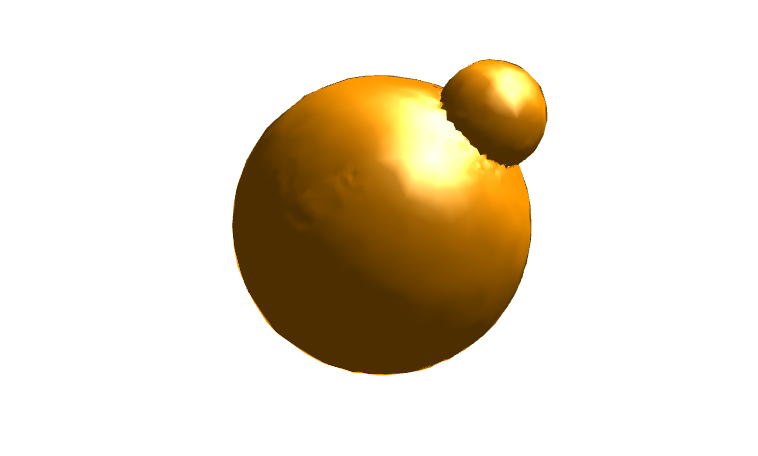

% Plot the lnps to do quality control
% Blebbed LNPs are a great simplification of the real structure, more
% accurate modelling would require different mesh approach
tau1 = blebbed_lnp{94,1}.tau_lipid_out;
tau2 = blebbed_lnp{94,1}.tau_aqueous_out;
tau3 = blebbed_lnp{94,1}.tau_interface;

figure;
plot(tau1);
plot(tau2);
plot(tau3);
axis equal; grid on; camlight;

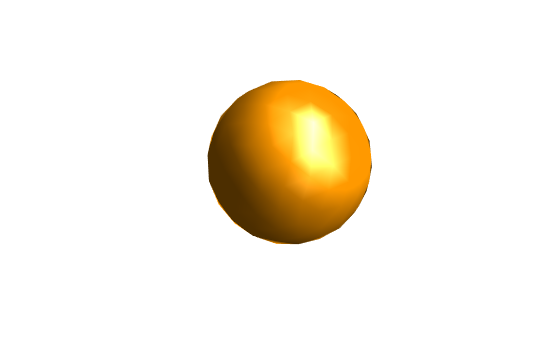

% Plot the lnps to do quality control
% Blebbed LNPs are a great simplification of the real structure, more
% accurate modelling would require different mesh approach
tau1 = empty_lnp{4,1}.tau;

figure;
plot(tau1);
axis equal; grid on; camlight;